Hi there! In this live script, we are gonna show how does Lab1 of Image Processing work. Let's begin with the detailed tutorial of the PDF about dealing with images in Matlab. 

## Image Processing in Matlab

The first thing that we should do is load an image with the *imread *function; if you check the image 'lena.png' (you should better get used to it cause you are going to use it a lot!), you'll see that it's a 256 x 256 image in grayscale (you can check it out by using the *size()* function.)

a = imread('lena.png');

Error using imread>get_full_filename (line 569)
File "lena.png" does not exist.

Error in imread (line 371)
    fullname = get_full_filename(filename);

size(a)

Moreover, if you want to see the image, you can use the *imshow *function, and cool stuff can be done with some tools such as the *Data Cursor*.

imshow(a)
title('Grayscale Lena')

Besides, you can acces any point in the image and see its value, just by setting the pixel position between brackets. Let's check, for instance, the position (10,20) of a, which will indicate the value of the image pixel in the 10th row and 20th column. 

a(10,20)

As you can see, the grayscale value at position (10,20) is 167. 

From now on, you'll perform several operations on top of images. As an example, imagine you want to change the value of a particular pixel (row 121, columns 126) to zero. 

a(121,126) = 0;
imshow(a)
title('Lena with 1 pixel modified')

With this line, you changed one single pixel of this image, and bearing in mind that it contains more than 65000 pixels itself (256*256), you will barely see the difference, right? 

In order to produce changes to the image that are visible, you have to change the grayscale value of groups of pixels at the same time. In this simple examples, we'll build a "thug" version of Lena, placing some black sunglasses on top of her face.

We'll start with the top part of the glasses, that will go from rows 126 to rows 133 and columns 121 to 180; it is as simple as indicating these positions with a vector, using " : ". 

a(126:133,121:180) = 0;
imshow(a)
title('Almost Thug Lena')

You can see that we drawn a beautiful rectangle in the above-mentioned rows and columns. In order to end it up, we'll add the two last parts of the sunglasses...

a(133:142, 121:148) = 0;
a(133:142, 158:180) = 0;
imshow(a)
title('Thug Lena')

## Types of Images

As you might have seen before, the image we loaded was stored in a uint8 matrix. Although it is pretty complex and messy to explain, uint8 images consider grayscale values to be within 0 and 255 (2^8), where 0 means black and 255 means white. 

However, there are other possible numerical types to deal with grayscale values: the *double *type is the most used, and instead of having a range of 0-255, it goes from 0-1, thus allowing decimals. In order to convert an image to double, it is as simple as load it whilst using the *im2double *function:

lenaDouble = im2double(imread('lena.png'));
imshow(lenaDouble)
title('Lena in Double Type')

**Warning:** if you have a matrix of doubles and its values are higher than 1, those will be clipped and all the image will look white. In a similar way, if you have a uint8 matrix and its values go from 0 to 1, the images will be dark af. Be consistent!!!

Finally, we have binary images, build up only with booleans that express if a condition is satisfied or not. For instance, let's threshold Lena image (in doubles), by setting to 1 those pixels with a higher grayscale value than 0.4.

lenaBinTh = lenaDouble > 0.4;
imshow(lenaBinTh)

The displayed mask corresponds to a logical matrix that only contains 0's and 1's.

If we want to combine two thresholds (e.g. threshold grayscale values from 0.4 to 0.7), you can combine two masks by multiplying them pixelwise (True * True = True; True * False = False). These masks will be used a posteriori in exercise 2! 

lenaBinThB = lenaDouble < 0.7;
lenaBin2Th = lenaBinTh.*lenaBinThB;
imshow(lenaBin2Th)

## Operations with Images

clearvars

Given that images are, after all, basic matrices, many operations can be performed: Some of these operations have little sense (such as the product of matrices). In contrast, the sum of matrices is a mixture of the two images. 

Multiplication of a matrix by some constant, or addition/subtraction of the same constant to/from all elements, produces the lighter or darker image.

For instance, let's merge Lena and Barbara! 

lena = imread('lena.png');
barbara = imread('barbara.png');
imshow(lena+barbara)

However, as you might have seen, the output image is too bright, as it has many values that, with this simple sum, exceed 255 (pure white). In order to perform a proper mix, a weighted sum has to be performed where the weights sum to one (weightLena + weightBarbara = 1):

weightLena = 0.5; % Try to change it!
weightBarbara = 1-weightLena; 
imshow(weightLena*lena + weightBarbara*barbara) 

Other simple operations could be multiplying all pixels in the image by a constant (or adding it). As an example, if we multiply by a constant value smaller than 1, we'll see a darker image. 

constFac = 0.5; % change it and see what happens
imshow(constFac * lena)

## Color Spaces

Idk about you, but until this point images seem a little boring, mainly because we are losing its main fun... Color! In this section we'll see how is color interpreted while loading images.

First, we'll use to worldwide known RGB colorspace, which will have 3 channels: Red - Green - Blue. 

lenaColor = im2double(imread('lena_color.png'));
size(lenaColor)
imshow(lenaColor)

 As you see now, the image does not only have rows and columns, but is also has channels (third dimension). In order to access the different channels, we have to take all rows and colums (with " : ") and specify the desired channel. 

r_lena = lenaColor(:,:,1);
g_lena = lenaColor(:,:,2);
b_lena = lenaColor(:,:,3); 

And now, we'll visualize each channel independently; but... Do you think that the red channel itself will look red? 

imshow(r_lena)
size(r_lena)

Uhlala... It does not! The reason is quite simple, this channel is a single channel of size 256x256, so it is not possible to display color. However, the content of the red channel indicates with brightness which pixels of the image look bright and which ones don't. For instance, you can spot that the whole Lena face is kind of red-ish, so in the channel image it has an almost constant and bright value. This means that bright values in the channel indicate the presence of red at that specific pixel in the color image (watch out, cause it may also have green and blue components!). 

We can again perform several operations on top of this image, such as changing the tonality of specific channels in a region of pixels. We'll repeat the example of the sunglasses, but instead of having a "thug Lena", we'll have a "Hawkers Lena", with some fashion green-blue sunglasses.  

After working with the different channels indepently, the function *cat *can be used to concatenate back into a 3-channel image. 

g_lena(126:133,121:180) = 1; % Modify Green Channel 
b_lena(133:142, 121:148) = 1; % Modify Blue Channel (1st part)
b_lena(133:142, 158:180) = 1; % Modify Blue Channel (2nd part)
lenaHawk = cat(3, r_lena, g_lena, b_lena);
imshow(lenaHawk)
title('Hawkers Lena')

However, as you might have seen in theory lectures, RGB is not the only existing colorspace. As a matter of fact, the Hue-Saturation-Value colorspace is also interesting. A matrix *y *in the HSV Colorspace contains:

- y(:,:,1) contains Hue information, which represents color tonality. This number is often expressed as an angle between 0 and 360, but due to Matlab interpretations, the current Hue is within the range of 0-255. This conversion can be done with a basic rule of three operations.

- y(:,:,2) contains Saturation information, which tells how pure a color is (this is, the amount of mixed pure white light). This value is often expressed as a percentage, but once again, Matlab casts it into a 0-255 range. The higher the saturation is, the larger number of grayscale tonalities can be found (100% saturation == pure color).

- y(:,:,3) contains Value information, which contains grayscale information of the specific pixel. Again, this feature is often expressed in a percentage, but when using Matlab, values must be converted again to the 0-255 range.

HSV is much more useful than RGB to perform, for instance, color filters, as the Hue channel works better to find out regions of an image with a particular tonality... Keep that in mind! 

Matlab already has functions to deal with different colorspaces (e.g. *rgb2hsv*); however, when trying to visualize images, make sure you are back in RGB color space (*hsv2rgb*) or you won't understand its content. 

im_rgb = im2double(imread('lena_color.png'));
% Convert into HSV colorspace
im_hsv = rgb2hsv(im_rgb);
im_hue = im_hsv(:,:,1);
im_sat = im_hsv(:,:,2);
im_val = im_hsv(:,:,3);

% Random operations
im_hue(51:100,51:100) = 0.5; % Set to a blue-ish tone
im_sat(101:150,101:150) = 0.9; % Saturate the color 
im_val(151:200,151:200) = 0.2; % Set a low value (~ grayscale value)
im_hsv = cat(3, im_hue, im_sat, im_val);

% Go back to RGB and display
im_rgb = hsv2rgb(im_hsv);
imshow(im_rgb); 

You are... ready to go! 

## LAB 1

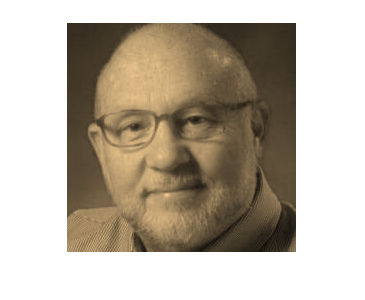

%Exercise 1: Sepia Effect. 
image_rgb = im2double(imread('Cientefico.jpeg'));
%convert a HSV
image_hsv = rgb2hsv(image_rgb);
image_hue = image_hsv(:,:,1);
image_sat = image_hsv(:,:,2);
image_val = image_hsv(:,:,3);
%per implementar un filtre sepia nomes volem canbiar el hue i la saturació
image_hue(:,:) = 0.1;
image_sat(:,:) = 0.4;
%actualitzem la imatge
im_hsv = cat(3, image_hue, image_sat, image_val);
im_rgb = hsv2rgb(im_hsv);
imshow(im_rgb); 

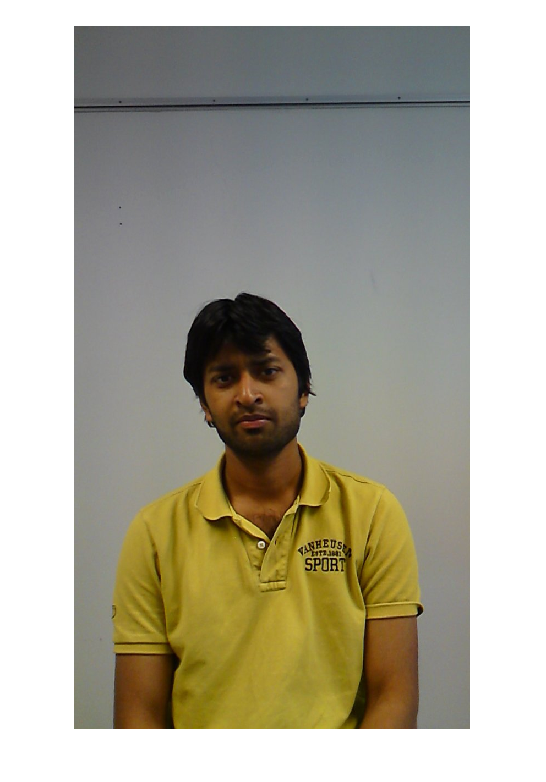


%Exercise 2:  

image_a = im2double(imread('FG1P.jpg'));
image_b = im2double(imread('BG1P.jpg'));
%imatge original
imshow(image_a);

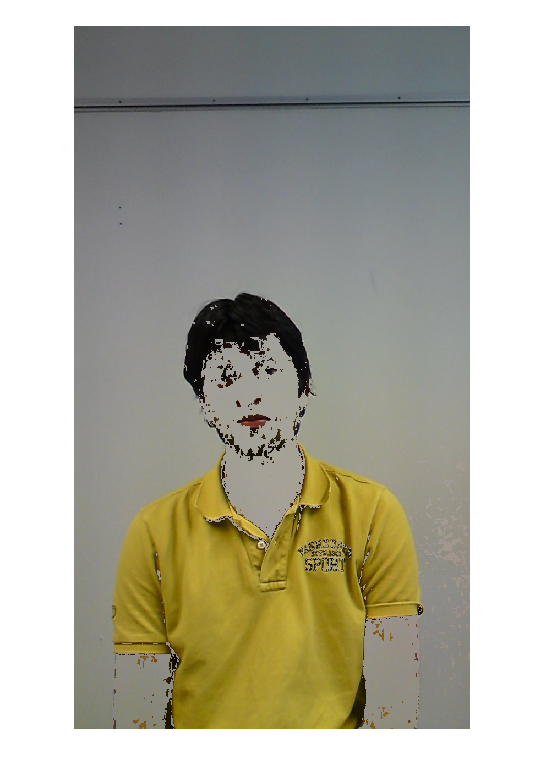

%convertim a hsv
image_hsv_a = rgb2hsv(image_a);
image_hsv_b = rgb2hsv(image_b);
image_hue_a = image_hsv_a(:,:,1);

%creem 2 mascares, les de la pell i l'altre

h1 = image_hue_a > 0.05;
h2 = image_hue_a < 0.098;

mask1 = h1.*h2;
mask2 = 1-mask1;
final = (image_a.*mask2)+(image_b.*mask1);
imshow(final);

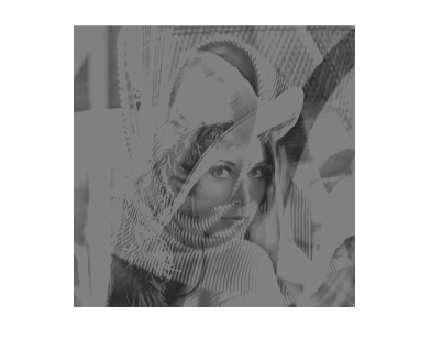


%Exercise 3

%1 bytes
image_a1 = im2uint8(imread('lena.png'));
image_b1 = im2uint8(imread('barbara.png'));
%1.1
final11 = (image_a1+image_b1)/2;
%1.2
final12 = (image_a1/2)+(image_b1/2);

%2 doubles
image_a2 = im2double(imread('lena.png'));
image_b2 = im2double(imread('barbara.png'));
%2.1
final21 = (image_a2+image_b2)/2;
%2.2
final22 = (image_a2/2)+(image_b2/2);

imshow(final11);

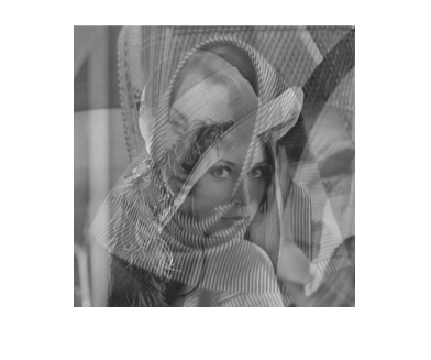

imshow(final12);

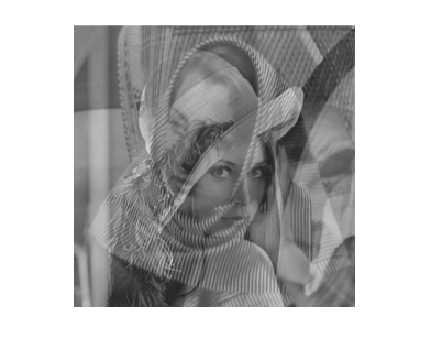

imshow(final21);

imshow(final22)